# MIMO Channel Estimation with interpolation

## Steps:

- Load the dataset: LS estimated channel at the pilot location, and the actual MIMO channel

- Split them into train, validation and test set

- Split them into real and imag parts

- Interpolate the Input data to match the size of output

- Save the weights and simulate to compare it with LS and MMSE techniques

### Load the dataset:

data_input = load('combined_data_1.mat');
data_output = load('combined_labels_1.mat');


### 2. Split into train, validation and test 

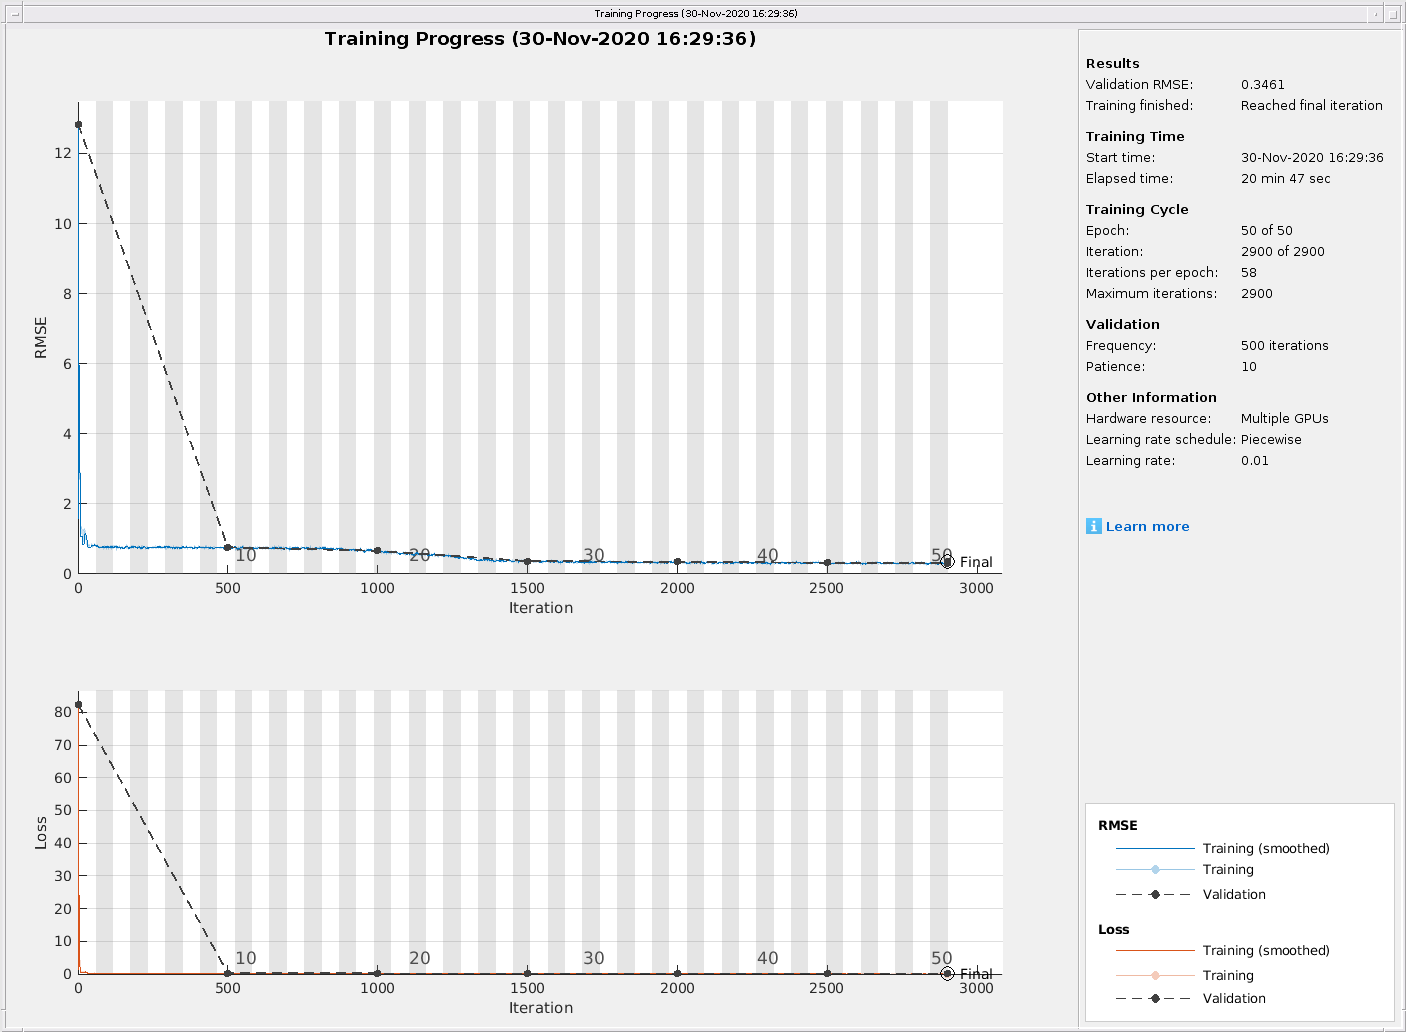

mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


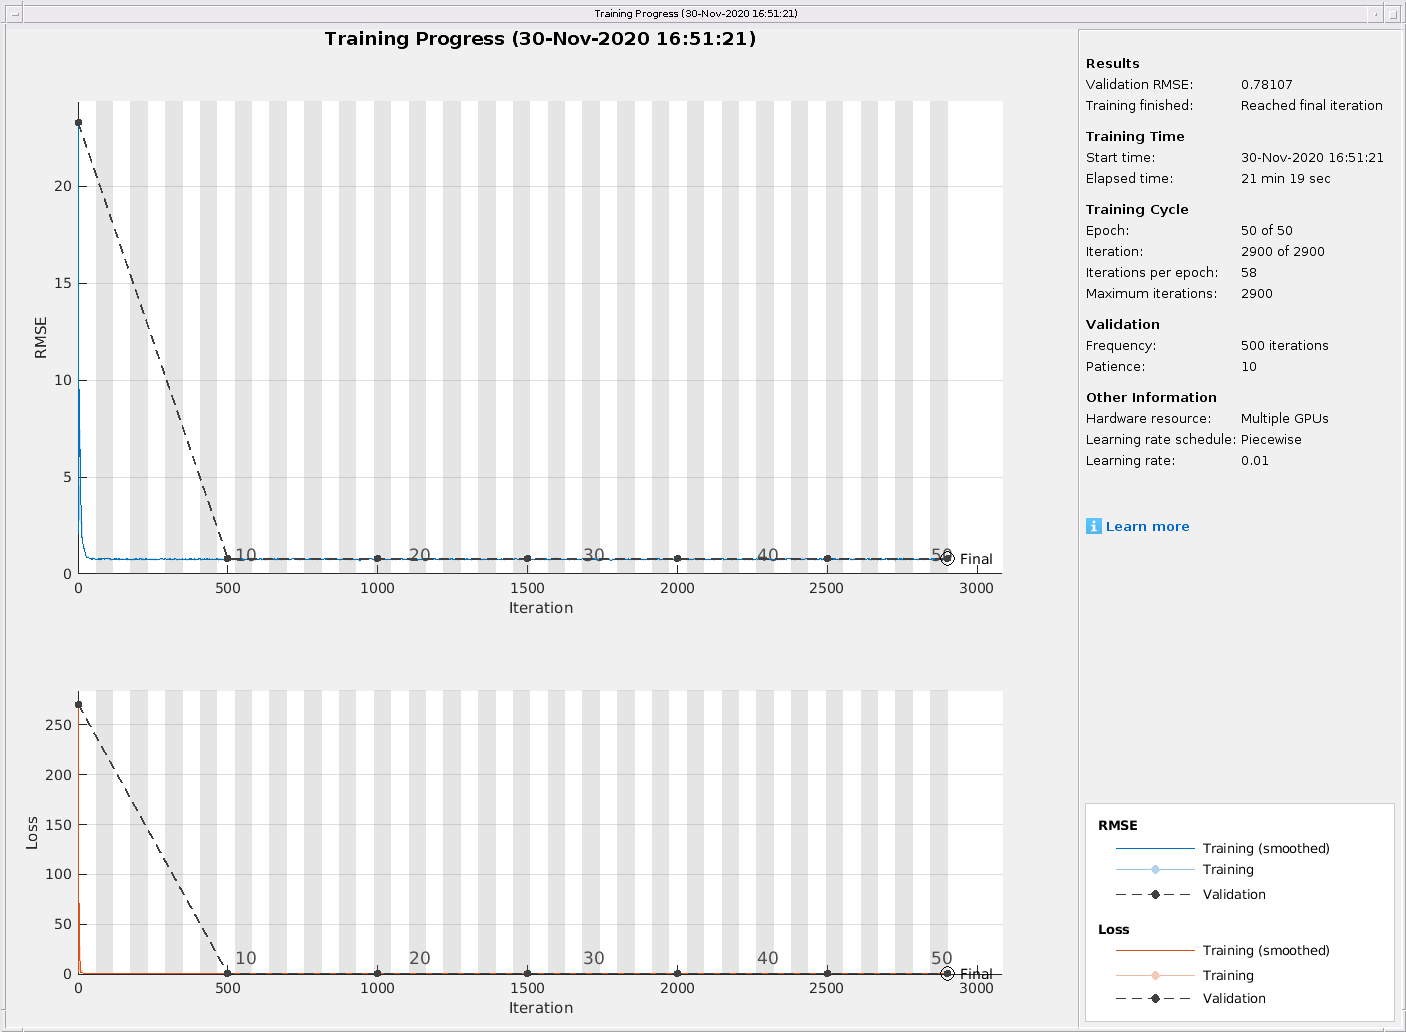

mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


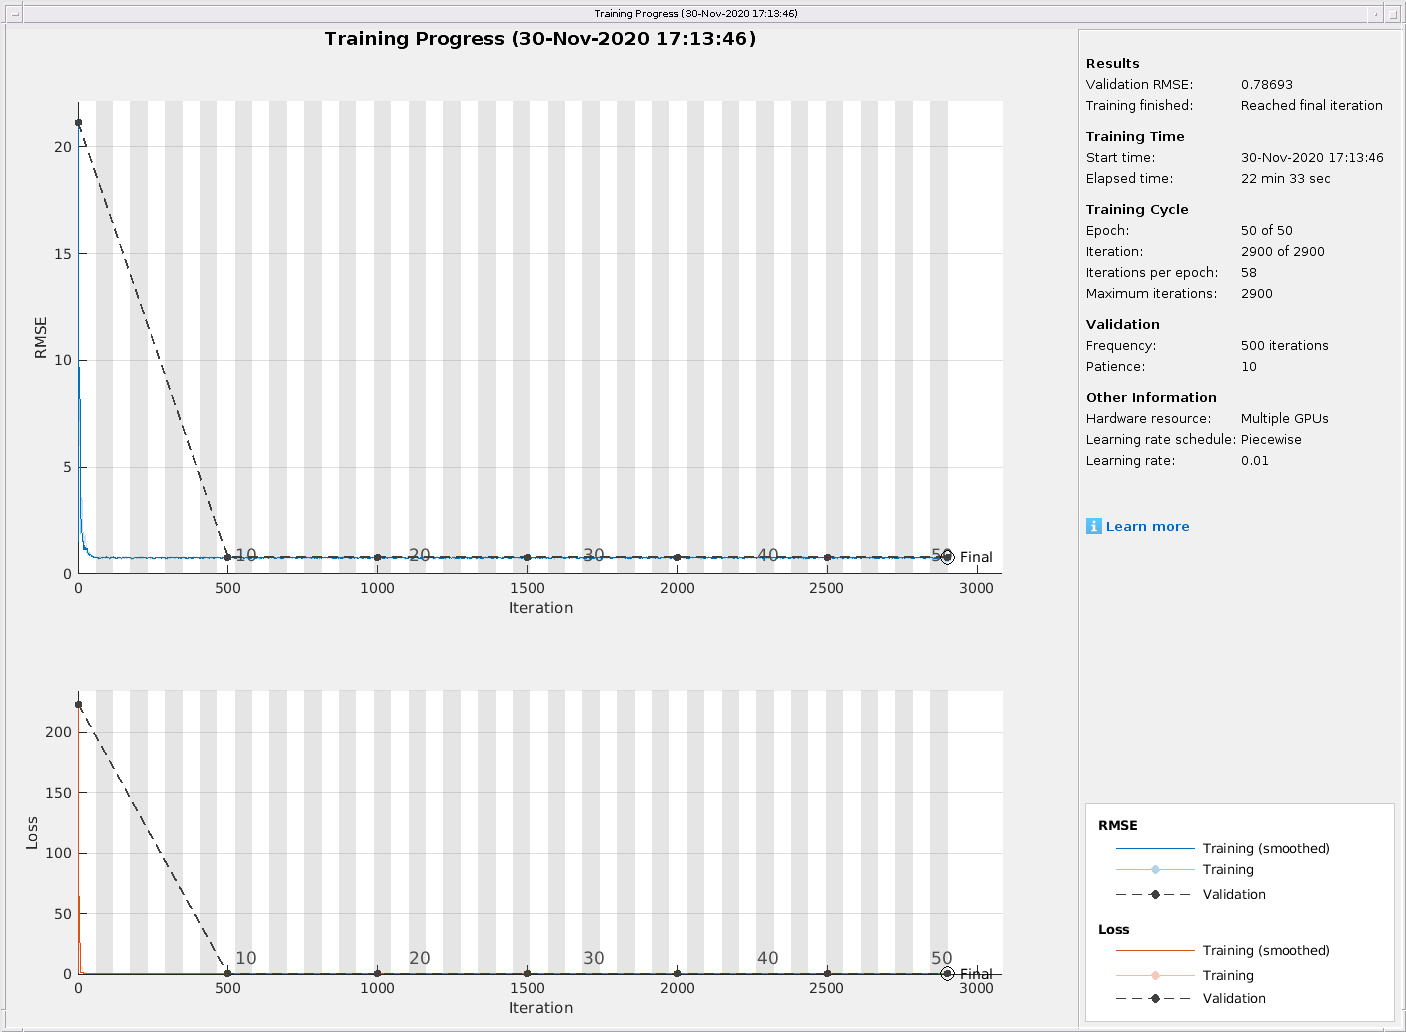

mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


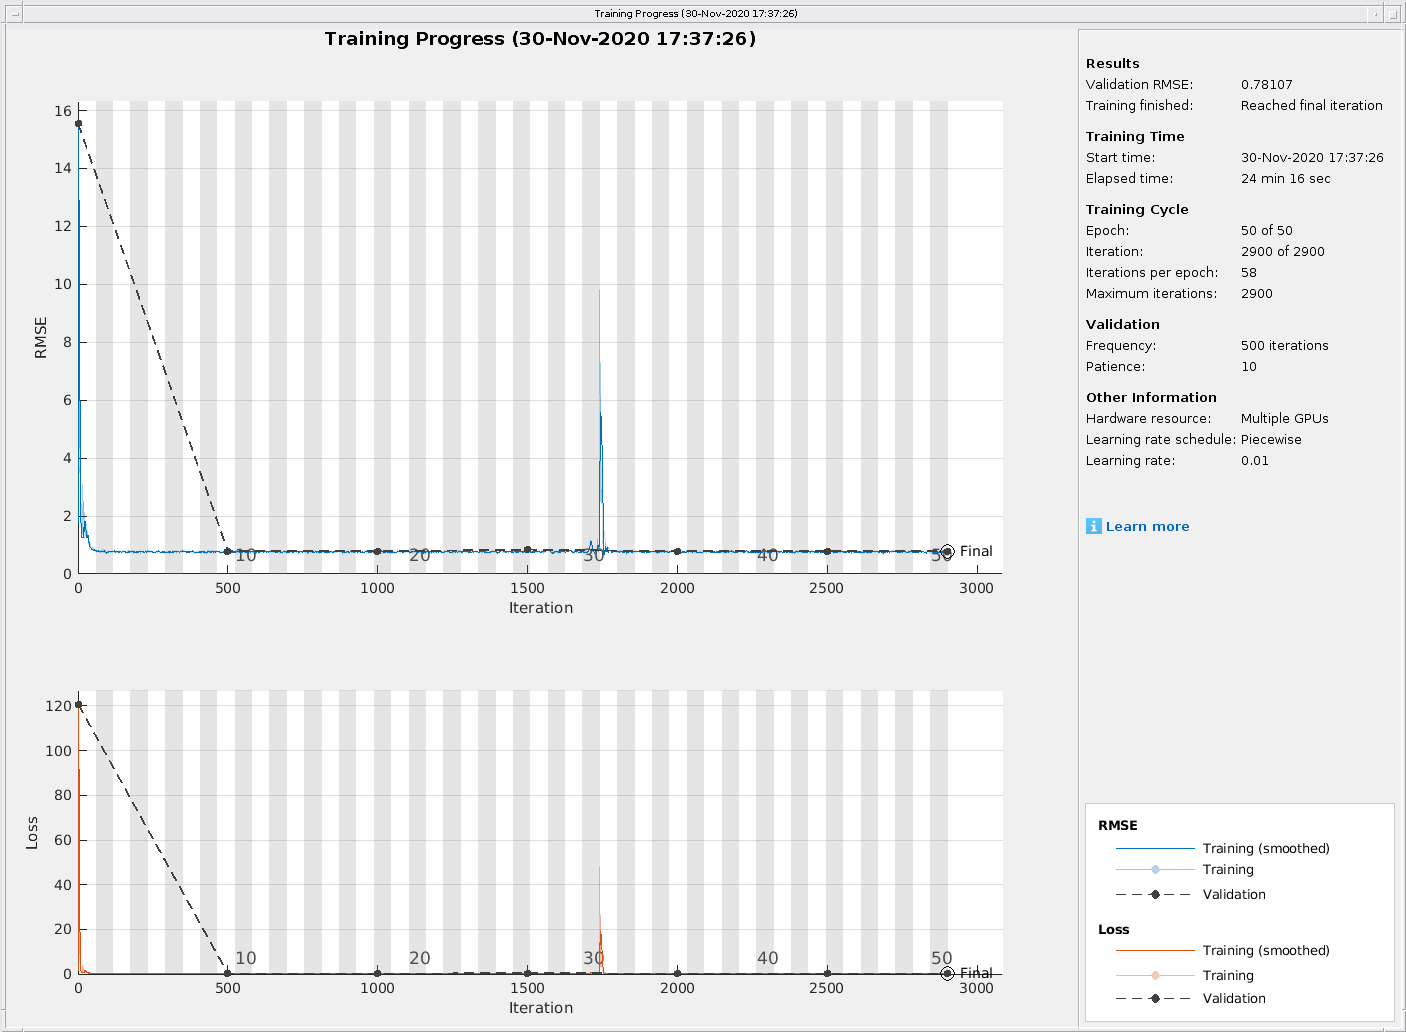

mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


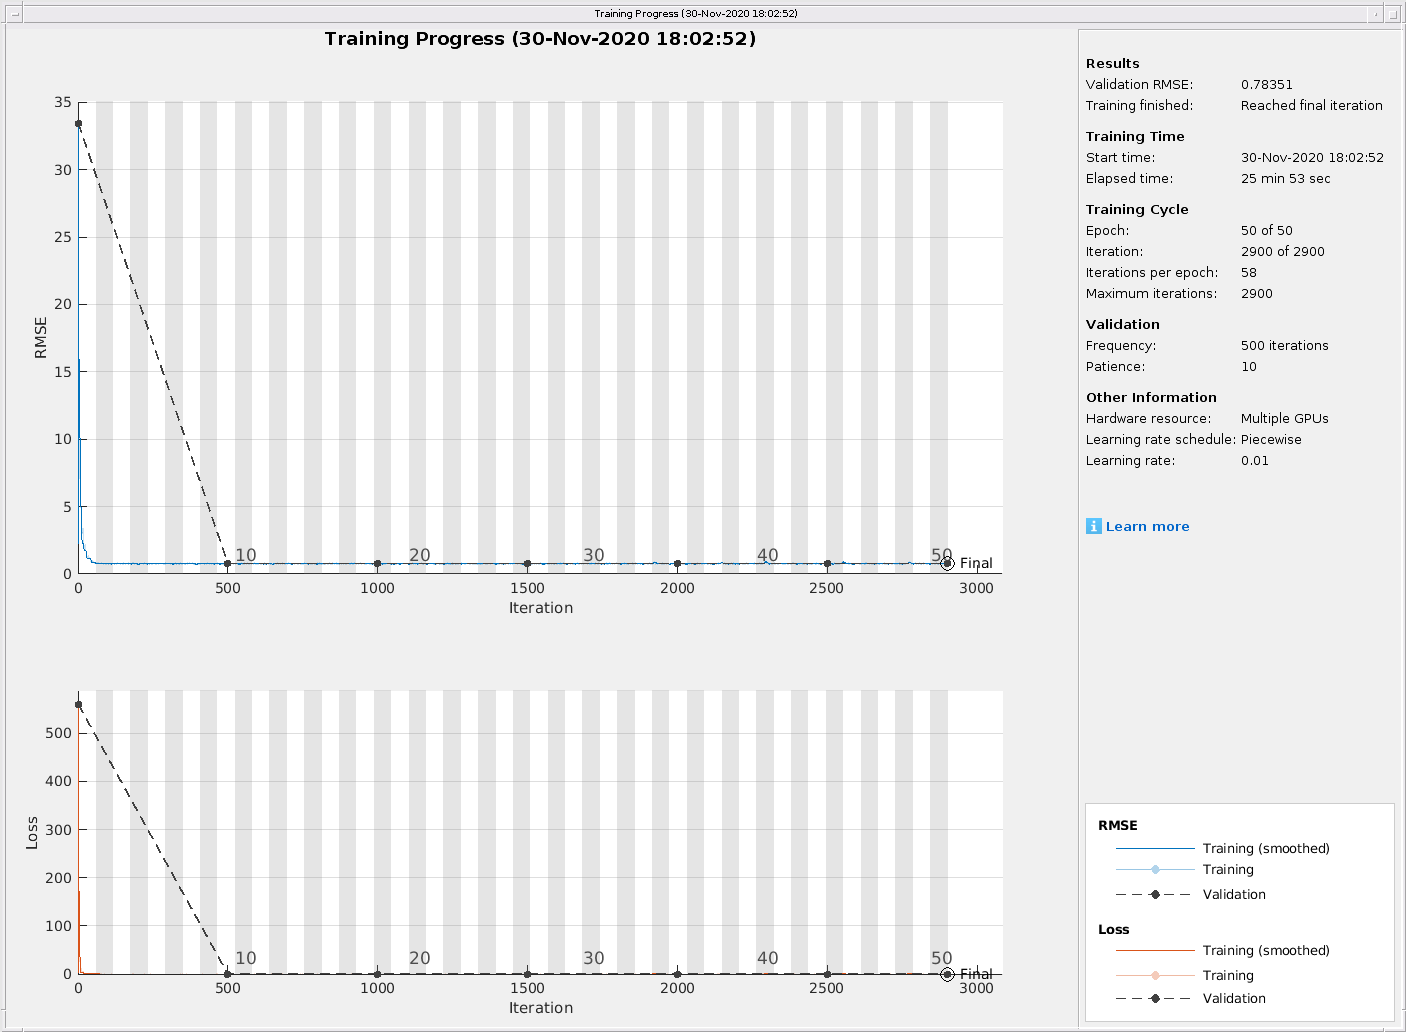

mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


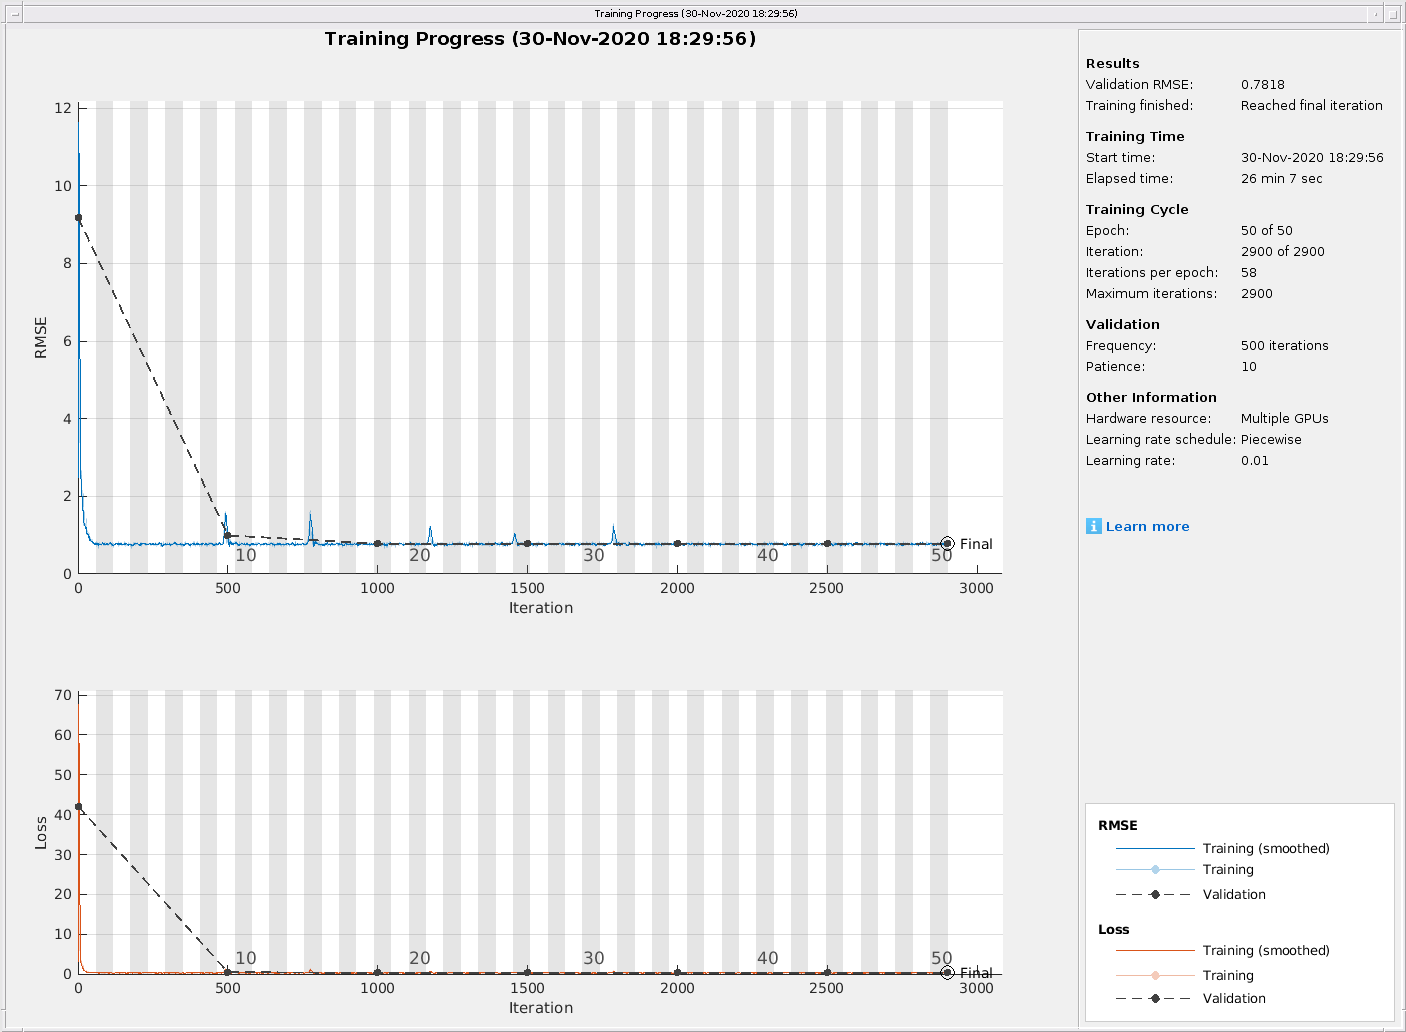

mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


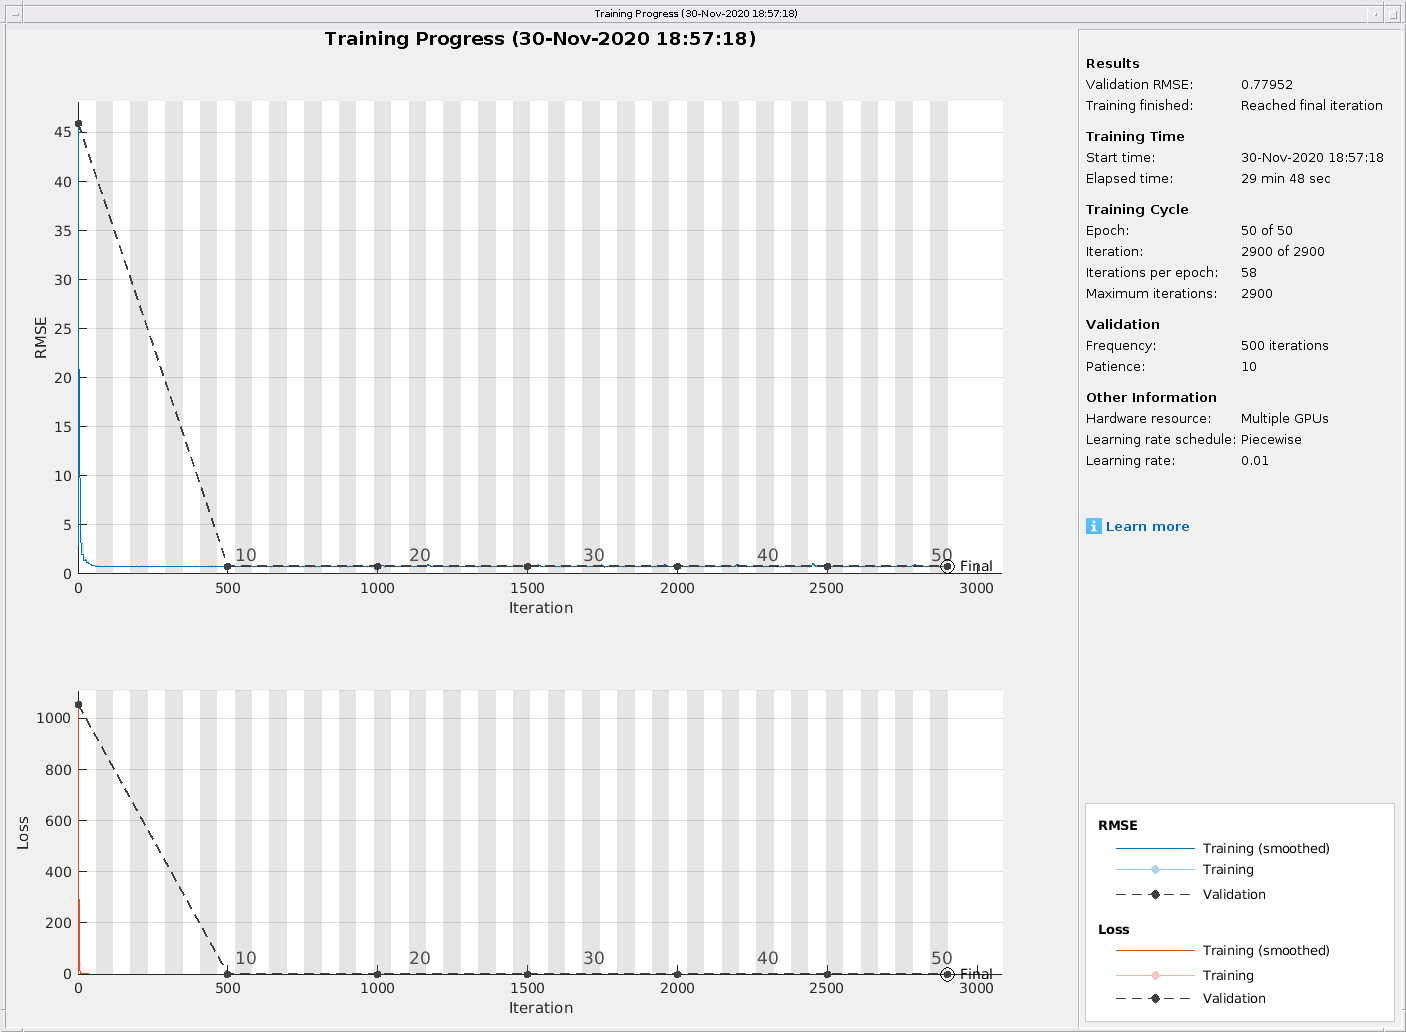

mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×2900 double]
      TrainingRMSE: [1×2900 double]
    ValidationLoss: [1×2900 double]
    ValidationRMSE: [1×2900 double]
     BaseLearnRate: [1×2900 double]


Lab 1: 


% Taking Nant = 4
RMSE_rms =[];
RMSE_pilot=[];
for i = 1:12
for l =1:size(data_input.combined_data{i,1},3)
    x=norm(data_input.combined_data{i,1}(:,:,l),'fro');
    if(x==0)
    data_input.combined_data{i,1}(:,:,l)=data_input.combined_data{i,1}(:,:,l)*10^9;
    else
    data_input.combined_data{i,1}(:,:,l)=data_input.combined_data{i,1}(:,:,l)/x;
    end
    x=norm(data_output.combined_labels{i,1}(:,:,l),'fro');
    if(x==0)
    data_output.combined_labels{i,1}(:,:,l)=data_output.combined_labels{i,1}(:,:,l)*10^9;
    else
    data_output.combined_labels{i,1}(:,:,l)=data_output.combined_labels{i,1}(:,:,l)/x;
    end
end
Nant = size(data_input.combined_data{i,1},1);
Ncarr = size(data_output.combined_labels{i,1},2);
pilot_cols = 1:4:16;
Nuser = size(data_input.combined_data{i,1},3);
data_input2 = zeros(Nant,Ncarr,Nuser);
for j=1:Nuser
    data_input2(:,:,j) = pilot_interpolate(data_input.combined_data{i,1}(:,:,j),pilot_cols,Nant,Ncarr);
end
train_data = zeros(Nant,2*Ncarr,30000); 
train_label= zeros(Nant,2*Ncarr,30000);
val_data = zeros(Nant,2*Ncarr,1500); 
val_label = zeros(Nant,2*Ncarr,1500); 
%test_data = zeros(Nant,2*Ncarr,1500);
%test_label = zeros(Nant,2*Ncarr,1500);
real_pos = 1:2:32;
train_data(:,real_pos,:) = real(data_input2(:,:,1:30000));
train_label(:,real_pos,:) = real(data_output.combined_labels{i,1}(:,:,1:30000));
val_data(:,real_pos,:) = real(data_input2(:,:,30001:31500));
val_label(:,real_pos,:) = real(data_output.combined_labels{i,1}(:,:,30001:31500));
%test_data(:,real_pos,:) = real(data_input2(:,:,31501:33000));
%test_label(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,31501:33000));


train_data(:,real_pos+1,:) = imag(data_input2(:,:,1:30000));
train_label(:,real_pos+1,:) = imag(data_output.combined_labels{i,1}(:,:,1:30000));
val_data(:,real_pos+1,:) = imag(data_input2(:,:,30001:31500));
val_label(:,real_pos+1,:) = imag(data_output.combined_labels{i,1}(:,:,30001:31500));
%test_data(:,real_pos+1,:) = imag(data_input2(:,:,31501:33000));
%test_label(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,31501:33000));
train_data = reshape(train_data,[Nant,2*Ncarr,1,size(train_data,3)]);
train_label = reshape(train_label,[Nant,2*Ncarr,1,size(train_label,3)]);
val_data = reshape(val_data,[Nant,2*Ncarr,1,size(val_data,3)]);
val_label = reshape(val_label,[Nant,2*Ncarr,1,size(val_label,3)]);

%plot_random_samples(train_data,train_label,'contour','training_data.png');




layers_1 = [...
        imageInputLayer([Nant 2*Ncarr 1],'Normalization','none','Name','Input')
        convolution2dLayer(10,128,'Padding','same','Name','cnn1')
        batchNormalizationLayer('Name','b1')
        reluLayer('Name','reLu1')
        convolution2dLayer(7,64,'Padding','same','Name','cnn2')
        batchNormalizationLayer('Name','b2')
        reluLayer('Name', 'reLu2')
        convolution2dLayer(5, 32,'Padding','same','Name','cnn_new')
        reluLayer('Name','relu_new')
        convolution2dLayer(3,16,'Padding','same','Name','cnn_new1')
        batchNormalizationLayer('Name','b3')
        reluLayer('Name', 'reLu5')
        convolution2dLayer(2,8,'Padding','same','Name','cnn_new2')
        batchNormalizationLayer('Name','b4')
        reluLayer('Name', 'reLu6')
        convolution2dLayer(5,1,'Padding','same','Name','cnn3')
        %batchNormalizationLayer('Name','b3')
        %reluLayer('Name','reLu3')...,
        ];

lgraph = layerGraph(layers_1);
layers_dn = dncnn_layers();
lgraph = addLayers(lgraph,layers_dn);
lgraph = connectLayers(lgraph,'cnn3','reLu3');
lgraph = connectLayers(lgraph,'reLu3','add_1/in2');

batchSize = 512;
valFrequency = 500;

   options = trainingOptions('adam', ...
    'ExecutionEnvironment','multi-gpu',...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',50, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'MiniBatchSize',batchSize, ...
    'ValidationData',{val_data, val_label}, ...
    'ValidationFrequency',valFrequency, ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',100,...
    'LearnRateDropFactor',0.1,...
    'L2Regularization',1e-5,...
    'ValidationPatience',10);
    
    [mimo_net,mimo_trainingInfo] = trainNetwork(train_data, ...
                                          train_label,lgraph,options)
    nanLoc = isnan(mimo_trainingInfo.ValidationLoss);
    ValidationLoss = mimo_trainingInfo.ValidationLoss(~nanLoc);
    RMSE_pilot = [RMSE_pilot ValidationLoss(end)]   ;
    nanLoc = isnan(mimo_trainingInfo.ValidationRMSE);
    ValidationRMSE = mimo_trainingInfo.ValidationRMSE(~nanLoc);
    RMSE_rms= [RMSE_rms mimo_trainingInfo.ValidationRMSE(end)];

                                      
snr = 0:4:40; %SNR in db
n=31500;

Ncarr = 16;
test_label = (data_output.combined_labels{i,1}(:,:,n:n+1500));
pilot_angles = linspace(0, pi/2,length(pilot_cols));
pilot = exp(1j*pilot_angles);
pilot_channel = data_output.combined_labels{i,1}(:,pilot_cols,n:n+1500);
test_label_dl = zeros(Nant,2*Ncarr,1501);
test_label_dl(:,real_pos,:) = real(data_output.combined_labels{i,1}(:,:,n:n+1500));
test_label_dl(:,real_pos+1,:) = imag(data_output.combined_labels{i,1}(:,:,n:n+1500));
test_label_dl = reshape(test_label_dl,[Nant,2*Ncarr,1,size(test_label_dl,3)]);
%train_data_dl = zeros(size(test_label_dl));
warning('off','all')
LS = [];
MMSE =[];
DL = [];
for snrdb=snr
    ls_rmse = 0;
    mmse_rmse = 0;
    dl_rmse = 0;
    received_loop = zeros(size(test_label_dl));
    for k=1:1500
        Pr_avg = norm(abs(pilot_channel(:,:,k)))^2;
        SNR    = 10^(.1*snrdb);
        Pn     = (Pr_avg/SNR)/2;
        rec = pilot_channel(:,:,k).*pilot;
        rec = rec + sqrt(Pn)*randn(size(rec,1), size(rec,2)) +...
        1i*sqrt(Pn)*randn(size(rec,1), size(rec,2)); % Add noise;
       
        [H_est_ls,H_est_mmse] = mimo_mmse_ls(Ncarr,Nant,rec,pilot,pilot_channel(:,:,k),pilot_cols);
        Rec = pilot_interpolate(rec,pilot_cols,Nant,Ncarr);
        received_loop(:,real_pos,k) = real(Rec);
        received_loop(:,real_pos+1,k) = imag(Rec);
        %test_data_dl = reshape(test_label_dl,[size(test_data_dl,1),size(test_data_dl,2),1]);
        %H_est_dl = predict(mimo_net,test_data_dl);
        %dl_rmse =  dl_rmse + sqrt(mean(abs(H_est_dl - test_label_dl(:,:,i)).^2,'all'));
        ls_rmse = ls_rmse + sqrt(mean(abs(H_est_ls - test_label(:,:,k)).^2,'all'));
        mmse_rmse = mmse_rmse + sqrt(mean(abs(H_est_mmse - test_label(:,:,k)).^2,'all'));
        
        
    end
    received_loop = reshape(received_loop,[Nant,2*Ncarr,1,size(test_label_dl,4)]);
    H_est_dl = predict(mimo_net,received_loop);
    dl_rmse =  dl_rmse + sqrt(mean(abs(H_est_dl - test_label_dl).^2,'all'));
    
    LS = [LS ls_rmse/1500];
    MMSE = [MMSE mmse_rmse/1500];
    DL = [DL dl_rmse];
    
end
    LS_ant(:,i) = LS;
    MMSE_ant(:,i)=MMSE;
    DL_ant(:,i)=DL;
end

figure1 = figure
plot(snr,LS,'k-s')
plot(snr,DL,'r-*')
plot(snr,MMSE,'b-o')
xlabel('SNR in dB')
ylabel('RMSE')
title('Comparison of DL, MMSE and LS')
legend('LS','DL','MMSE')
%savefig(figure1,'comparison.fig')


val_data2 = predict(mimo_net,val_data);
plot_random_samples(val_data2,val_label,'contour','val_data.png');